# ENEE631 Digital Image and Video Processing

# Final Project

## Topic: PDE-based Image Denoising

## Author: Mansur Shakipov

### Setup

% pic: 1 for cameraman, 2 for Lena
% sigm: 1 for light noise, 2 for harsh noise
pic = 2; sigm = 1;
mu = 0.0; sigma_ns = [5e-3 2e-2];
if pic==1
    I = im2double(imread("cameraman.tif"));
elseif pic==2
    I = im2double(rgb2gray(imread("lena.tif")));
end
In = imnoise(I,'gaussian',mu,sigma_ns(sigm));

### Denoising

x = optimize(I,In,@imgaussfilt,0.01,5)

x = 0.9768

Ig = imgaussfilt(In,x);
psnr(Ig,I)

ans = 30.5933

x = optimize(I,In,@tikh_reg,0.01,10)

Lambda = 3.826 | Number of iterations: 6.
Lambda = 6.184 | Number of iterations: 6.
Lambda = 2.368 | Number of iterations: 8.
Lambda = 1.468 | Number of iterations: 10.
Lambda = 0.911 | Number of iterations: 13.
Lambda = 0.567 | Number of iterations: 16.
Lambda = 0.961 | Number of iterations: 13.
Lambda = 0.870 | Number of iterations: 14.
Lambda = 0.917 | Number of iterations: 13.
Lambda = 0.895 | Number of iterations: 13.
Lambda = 0.886 | Number of iterations: 13.
Lambda = 0.880 | Number of iterations: 13.
Lambda = 0.876 | Number of iterations: 13.
Lambda = 0.874 | Number of iterations: 13.
Lambda = 0.873 | Number of iterations: 13.
Lambda = 0.872 | Number of iterations: 13.
Lambda = 0.871 | Number of iterations: 13.
Lambda = 0.871 | Number of iterations: 13.
Lambda = 0.871 | Number of iterations: 14.
Lambda = 0.871 | Number of iterations: 13.
Lambda = 0.871 | Number of iterations: 14.
Lambda = 0.871 | Number of iterations: 13.
Lambda = 0.871 | Number of iterations: 14.


x = 0.8708

Itr = tikh_reg(In,x);

Lambda = 0.871 | Number of iterations: 13.


psnr(Itr,I)

ans = 30.2048

x = optimize(I,In,@tv_min,0.01,1)

Mu = 0.39 | Number of iterations: 35.
Mu = 0.62 | Number of iterations: 49.
Mu = 0.24 | Number of iterations: 26.
Mu = 0.15 | Number of iterations: 20.
Mu = 0.10 | Number of iterations: 16.
Mu = 0.07 | Number of iterations: 13.
Mu = 0.04 | Number of iterations: 12.
Mu = 0.03 | Number of iterations: 12.
Mu = 0.05 | Number of iterations: 13.
Mu = 0.04 | Number of iterations: 12.
Mu = 0.04 | Number of iterations: 12.
Mu = 0.04 | Number of iterations: 12.
Mu = 0.04 | Number of iterations: 12.
Mu = 0.04 | Number of iterations: 12.


x = 0.0449

Itv = tv_min(In, x);

Mu = 0.04 | Number of iterations: 12.


psnr(Itv,I)

ans = 31.3400

tps = ["pm", "ch", "zh"];
xad = zeros(length(tps),1);
psnrad = zeros(length(tps),1);
for i=1:length(tps)
    xad(i) = optimize(I,In,@(I,par)anis_diff(I,par,tps(i),0),0.001,0.1);
    Iad = anis_diff(In,xad(i),tps(i),1);
    psnrad(i) = psnr(Iad,I);
    fprintf("%3s | %.3f\n", tps(i), psnrad(i));
end

Kappa = 0.029 | Number of iterations: 67.


 pm | 30.755


Kappa = 0.008 | Number of iterations: 63.


 ch | 31.573


Kappa = 0.031 | Number of iterations: 58.


 zh | 30.858


Iad_pm = anis_diff(In,xad(1),tps(1),1);

Kappa = 0.029 | Number of iterations: 67.


Iad_ch = anis_diff(In,xad(2),tps(2),1);

Kappa = 0.008 | Number of iterations: 63.


Iad_zh = anis_diff(In,xad(3),tps(3),1);

Kappa = 0.031 | Number of iterations: 58.


[~,mi] = max(psnrad);
fprintf("best: %s with PSNR = %.3f and param = %.4f\n", tps(mi), psnrad(mi), xad(mi));

best: ch with PSNR = 31.573 and param = 0.0076


x = optimize(I,In,@yk,0.01,1)

Kappa = 0.388 | Number of iterations: 30.
Kappa = 0.622 | Number of iterations: 28.
Kappa = 0.244 | Number of iterations: 35.
Kappa = 0.154 | Number of iterations: 45.
Kappa = 0.099 | Number of iterations: 63.
Kappa = 0.189 | Number of iterations: 40.
Kappa = 0.135 | Number of iterations: 50.
Kappa = 0.163 | Number of iterations: 43.
Kappa = 0.159 | Number of iterations: 44.
Kappa = 0.159 | Number of iterations: 44.
Kappa = 0.160 | Number of iterations: 44.
Kappa = 0.161 | Number of iterations: 44.
Kappa = 0.161 | Number of iterations: 44.
Kappa = 0.161 | Number of iterations: 44.
Kappa = 0.161 | Number of iterations: 44.


x = 0.1607

Iyk = yk(In, x);

Kappa = 0.161 | Number of iterations: 44.


psnr(Iyk,I)

ans = 30.7778

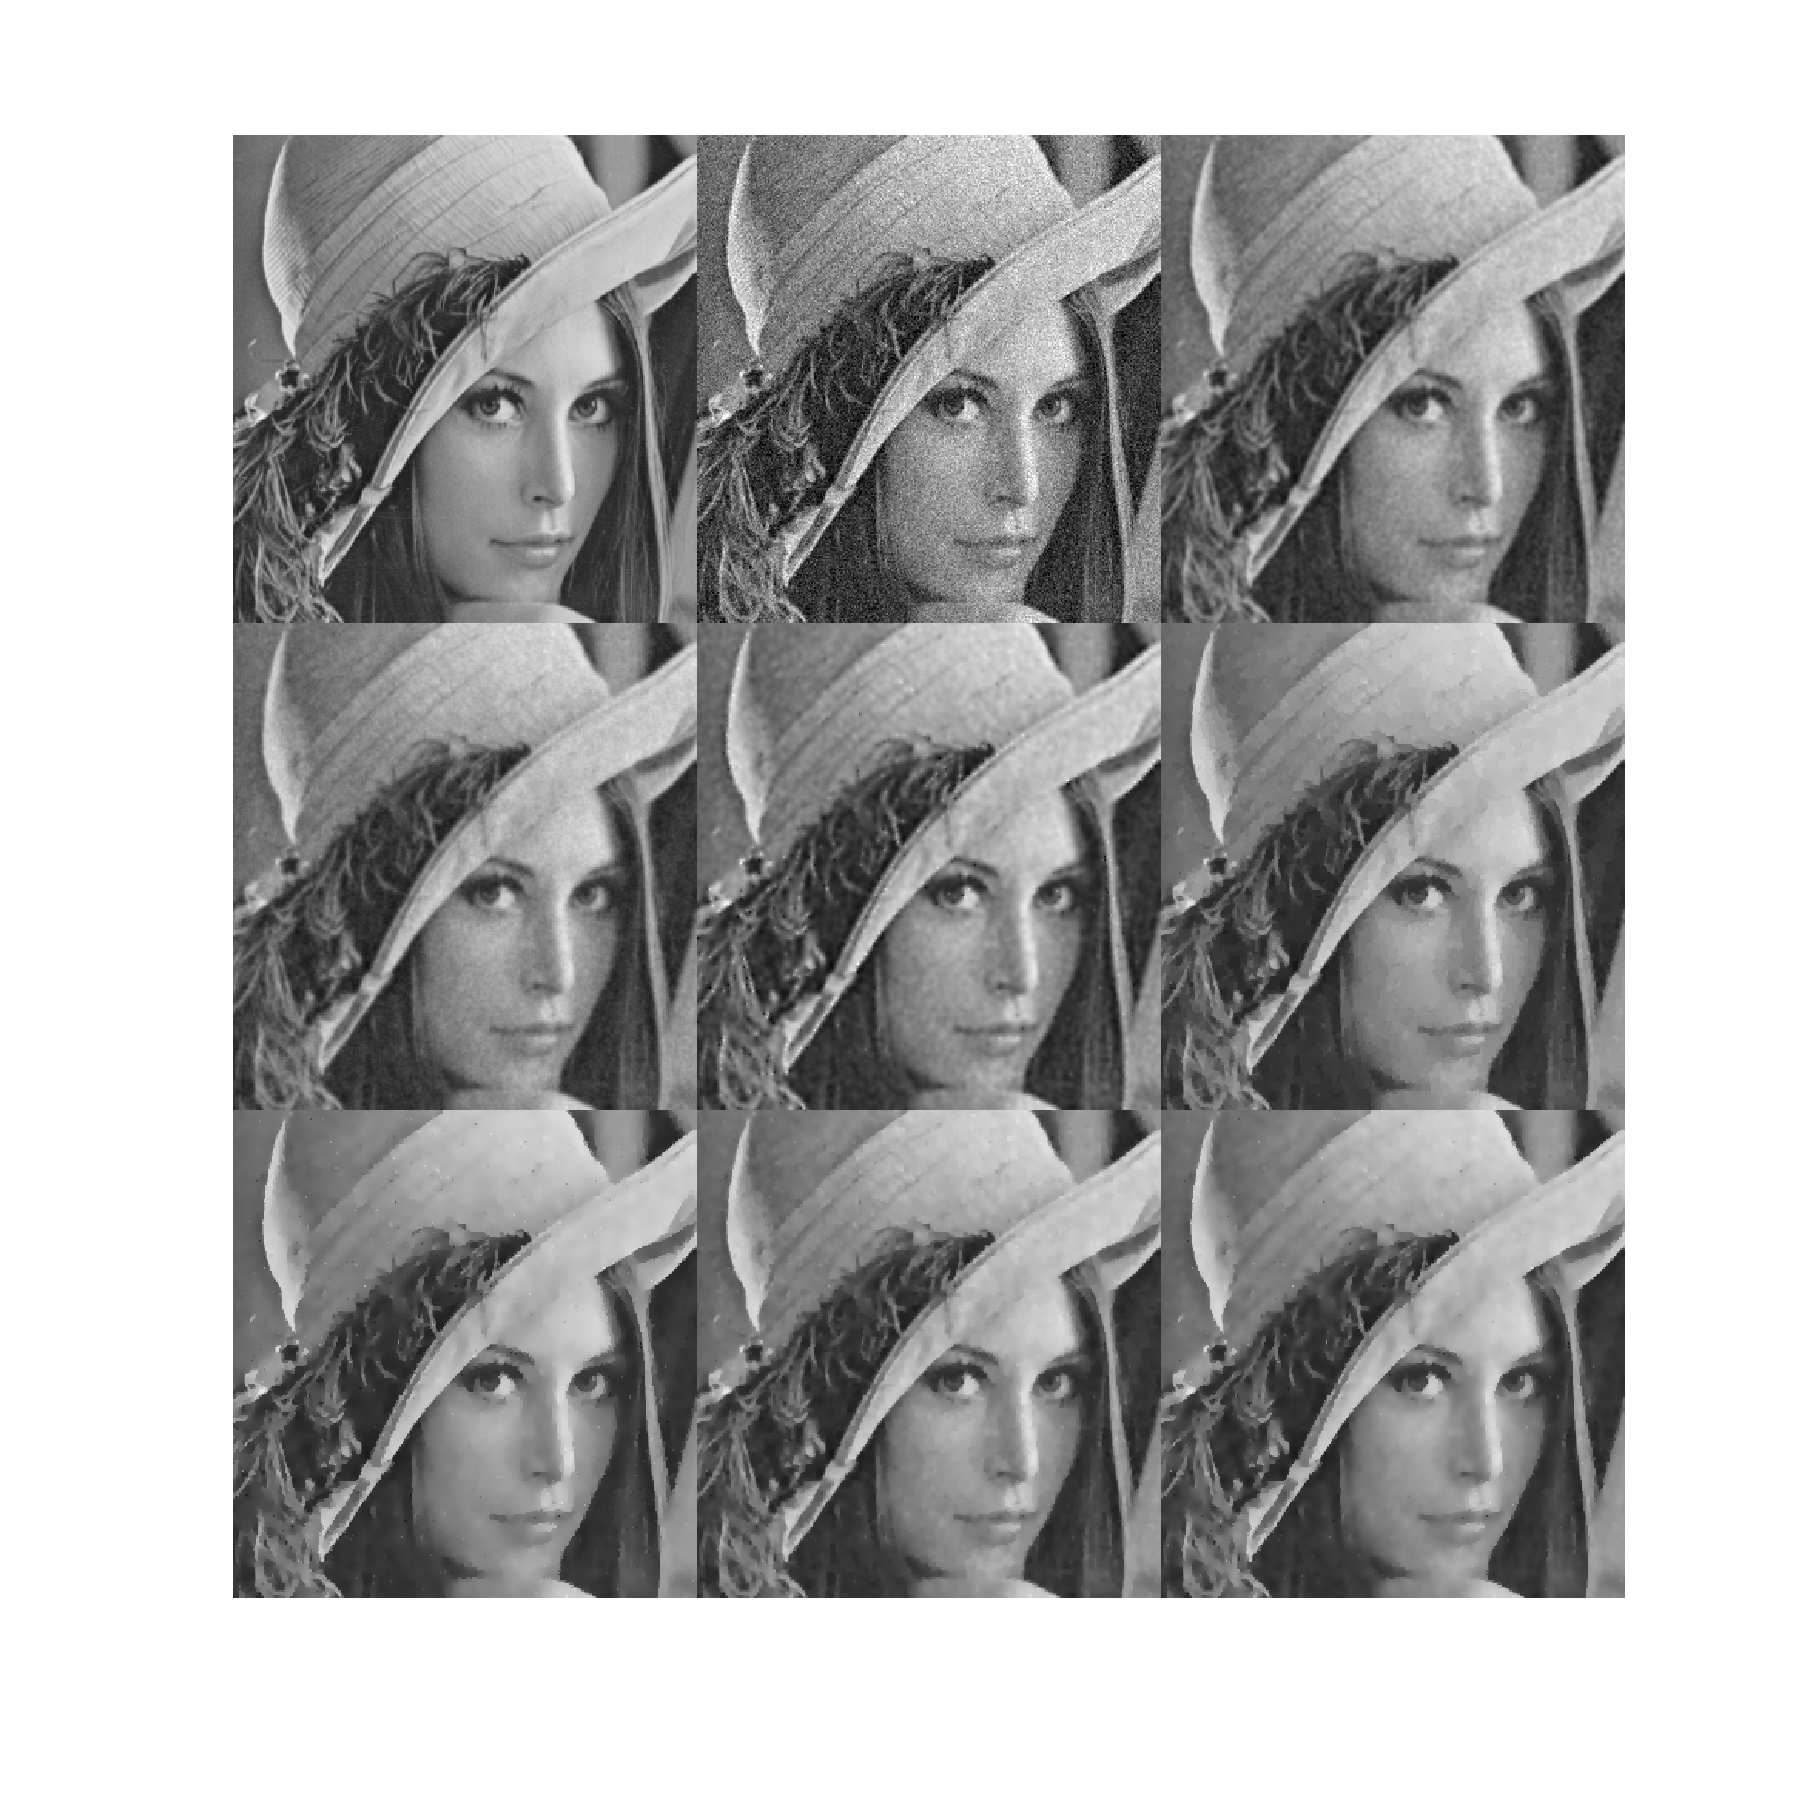

if pic==1
    sz = 100;
    lx = 20; rx = lx+sz;
    ly = 80; ry = ly+sz;
elseif pic==2
    sz = 300;
    lx = 100; rx = lx+sz;
    ly = 100; ry = ly+sz;
end

figure('Renderer', 'painters', 'Position', [10 10 900 900])
colormap gray(255)

Ibig = [I(lx:rx,ly:ry) In(lx:rx,ly:ry) Ig(lx:rx,ly:ry);
    Itr(lx:rx,ly:ry) Iyk(lx:rx,ly:ry) Itv(lx:rx,ly:ry); ...
    Iad_pm(lx:rx,ly:ry) Iad_ch(lx:rx,ly:ry) Iad_zh(lx:rx,ly:ry)];

imagesc(Ibig)
axis off

### PSNR

NIs = 8;
Is = cell(NIs,1);
Is{1} = In;
Is{2} = Ig;
Is{3} = Itr;
Is{4} = Iyk;
Is{5} = Itv;
Is{6} = Iad_pm;
Is{7} = Iad_ch;
Is{8} = Iad_zh;

names = ["Noisy","Gauss","Tikh","YK","TV","Anis pm", "Anis ch", "Anis zh"];
for i=1:NIs
    fprintf("%8s: %.3f\n",names(i),psnr(Is{i},I));
end

   Noisy: 23.034
   Gauss: 30.593
    Tikh: 30.205
      YK: 30.778
      TV: 31.340
 Anis pm: 30.755
 Anis ch: 31.573
 Anis zh: 30.858


function opt_param = optimize(I, In, method, pmin, pmax)
    func = @(par) -psnr(method(In,par),I);
    opt_param = fminbnd(func,pmin,pmax);
end